%% Idea : Rather than simultaneous optimization of all three gears, assume

bending_safety_target = 1.2;
wear_safety_target = 1.1;
target_gr = 2;
gb_rad_lim = 130;
%target_center_dist = 1000*(wheelbearing.internalDiameter - planetPin.diameter)/2;
target_center_dist = 38.5;
modules = 0.5:0.05:1.5; 
sunTeeths = zeros(size(modules));

for i = 1:1:length(modules)
    sunTeeths(i) = minSunTeeth(20,modules(i),sun,motor);
end

sunPitchDiameters = modules.*sunTeeths;
planetTeeths = floor(2 * (target_center_dist - sunPitchDiameters/2)./modules);
planetPitchDiameters = planetTeeths .* modules;
actual_center_dist = (sunPitchDiameters + planetPitchDiameters)/2;

sun_roots = zeros(size(modules));
sun_flanks = zeros(size(modules));
planet_roots = zeros(size(modules));
planet_flanks = zeros(size(modules));

J_sun = getGeometryFactor(sunTeeths);
J_planet = getGeometryFactor(planetTeeths)

J_planet =    -0.1251   -0.0687   -0.0275    0.0156    0.0456    0.0820    0.1089    0.1422    0.1652    0.1827    0.2067    0.2251    0.2501    0.2629    0.2758    0.2954    0.3086    0.3220    0.3354    0.3490    0.3625


for i = 1:1:length(modules)
    [sun_roots(i), sun_flanks(i)] = GearStress_Sun(25.4/modules(i),sunTeeths(i),planetTeeths(i),J_sun(i),gearbox.qualityFactor,sun.facewidth,planet.hardness,2.5,10);
    [planet_roots(i), planet_flanks(i)] = GearStress_Sun(25.4/modules(i),planetTeeths(i),sunTeeths(i),J_planet(i),gearbox.qualityFactor,planet.sunStage.facewidth,planet.hardness,2.5,10);
end

pass_criteria = sun_roots > bending_safety_target &...
                sun_flanks > wear_safety_target &...
                planetPitchDiameters+sunPitchDiameters/2 < gb_rad_lim &...
                planetTeeths./sunTeeths > target_gr;

passed = modules(pass_criteria)

passed =     1.3500    1.4000


min(passed)

ans = 1.3500

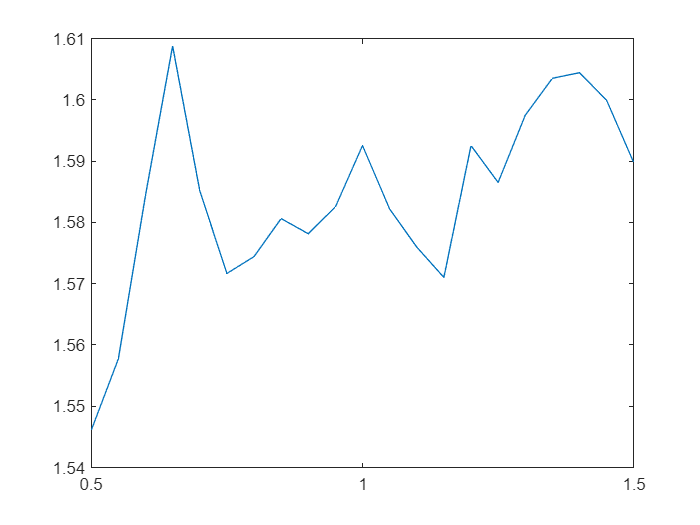

plot(modules,planet_flanks)

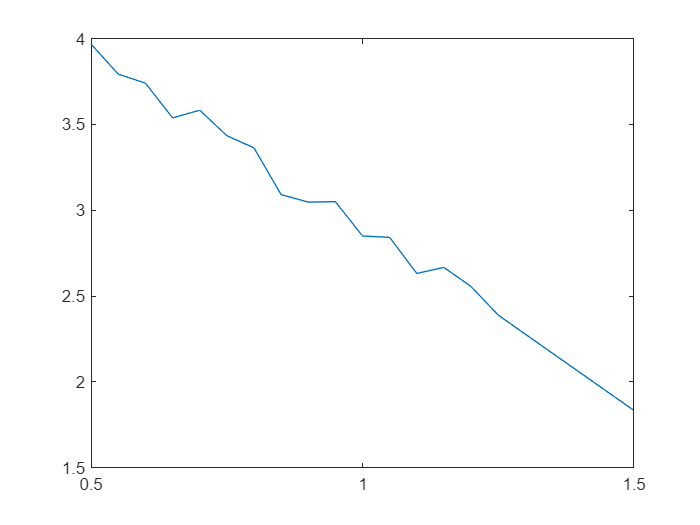

plot(modules,planetTeeths./sunTeeths)

function [min_sunteeth] = minSunTeeth(pressureAngle,module,sun,motor)
    backup_ratio = 1.2;
    deddendum_factor = sun.whole_depth_factor - sun.addendum_factor;
    tooth_height = sun.whole_depth_factor * module;
    rim_thickness = tooth_height*backup_ratio;
    effectiveInternalDiameter = sqrt((sun.internalDiameter/2+motor.keyProjHeight)^2+(motor.keyWidth/2)^2);
    pitchDiameter = 2*(rim_thickness+deddendum_factor*module+1000*effectiveInternalDiameter/2);
    min_sunteeth_rim = ceil(pitchDiameter/module);
    min_sunteeth_undercut = ceil(2/(sind(pressureAngle))^2);
    min_sunteeth = max(min_sunteeth_rim,min_sunteeth_undercut);
end